addpath('../utils/')
sympref('FloatingPointOutput', true); % display all symnums at 4 sigfigs

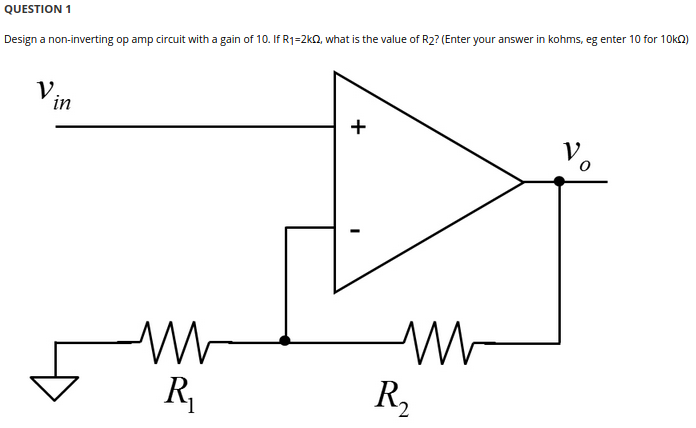

syms A_v v_o v_in R_1 R_2

constants = [
    R_1 == 2e3
    A_v == 10
]

$$constants = \left(\begin{array}{c} R_{1}=2000\\ A_{v}=10 \end{array}\right)$$


gain_eq = A_v == 1 + R_2 / R_1

$$gain\_eq = A_{v}=\frac{R_{2}}{R_{1}}+1$$


solve_for(R_2, [constants; gain_eq])

$$ans = 18000$$

**Question 2 **     

A non-inverting amplifier circuit has R1=10kΩ, and R2 = 91kΩ. The gain bandwidth product fT = 1MHz. What is the bandwidth of the closed loop amplifier? (Provide answer in kHz, eg, for 100kHz, enter 100)

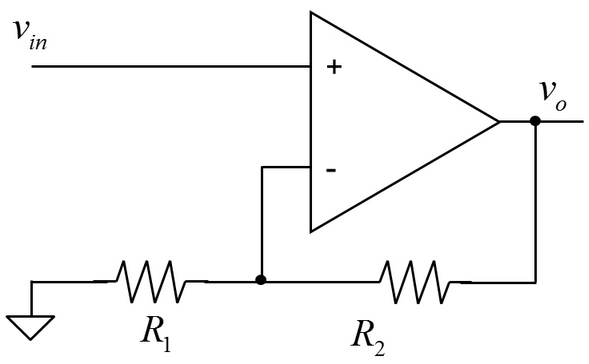

syms f_T f_3dB

constants = [
    R_1 == 10e3
    R_2 == 91e3
    f_T == 1e6
]

$$constants = \left(\begin{array}{c} R_{1}=10000\\ R_{2}=91000\\ f_{T}=1000000 \end{array}\right)$$


gain_eq = A_v == 1 + R_2 / R_1

$$gain\_eq = A_{v}=\frac{R_{2}}{R_{1}}+1$$

closed_loop_bandwidth = f_3dB == f_T / abs(A_v)

$$closed\_loop\_bandwidth = f_{\mathrm{3dB}}=\frac{f_{T}}{\left|A_{v}\right|}$$


solve_for(f_3dB, [constants; gain_eq; closed_loop_bandwidth])

$$ans = 9.9010e+04$$

**Question 3** 

If R1 = 20kΩ and R2 = 80kΩ in the circuit below, what value should resistor R3 be set to, to reduce the effect of input bias current? (Enter your answer in kΩ, eg 9.9 kΩ should be entered as 9.9) 

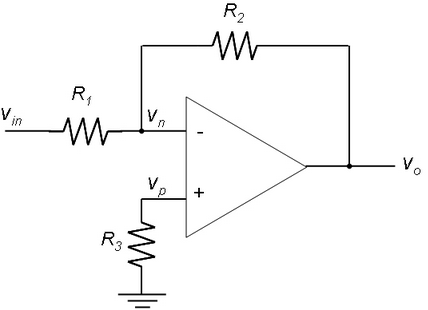

syms R_3 R_eq

constants = [
    R_1 == 20e3
    R_2 == 80e3
]

$$constants = \left(\begin{array}{c} R_{1}=20000\\ R_{2}=80000 \end{array}\right)$$


gain_eq = A_v == 1 + R_2 / R_1

$$gain\_eq = A_{v}=\frac{R_{2}}{R_{1}}+1$$

bias_curr_reduction = R_3 == zpar([R_1 R_2])

$$bias\_curr\_reduction = R_{3}=\frac{R_{1}\,R_{2}}{R_{1}+R_{2}}$$


solve_for(R_3, [constants; gain_eq; bias_curr_reduction])

$$ans = 16000$$

**Question 4**

For the difference amp below, R1 = 12kΩ and R2 = 22kΩ. Assuming power supply voltages of ±15V, what is the output Vo if Vin1 = -1.8V and Vin2 = 0.4V? (Enter answer in V)

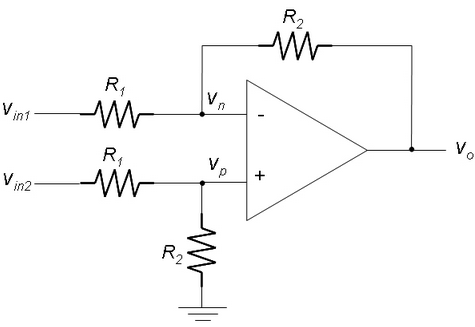

syms v_in1 v_in2

constants = [
    R_1 == 12e3
    R_2 == 22e3
    v_in1 == -1.8
    v_in2 == 0.4
]

$$constants = \left(\begin{array}{c} R_{1}=12000\\ R_{2}=22000\\ v_{\mathrm{in1}}=-1.8000\\ v_{\mathrm{in2}}=0.4000 \end{array}\right)$$


difference_amp = v_o == R_2 / R_1 * (v_in2 - v_in1)

$$difference\_amp = v_{o}=-\frac{R_{2}\,\left(v_{\mathrm{in1}}-v_{\mathrm{in2}}\right)}{R_{1}}$$


solve_for(v_o, [constants; difference_amp])

$$ans = 4.0333$$

**Question 5**

An instrumentation amp consists of three op amps, six internal resistors (R1) and one external variable resistor (R2) as shown below. If R1 = 30kΩ, R2 = 3.6kΩ, v1 = 4.97V and v2 = 5.03V, what is the voltage at point vb? (Enter answer in V)

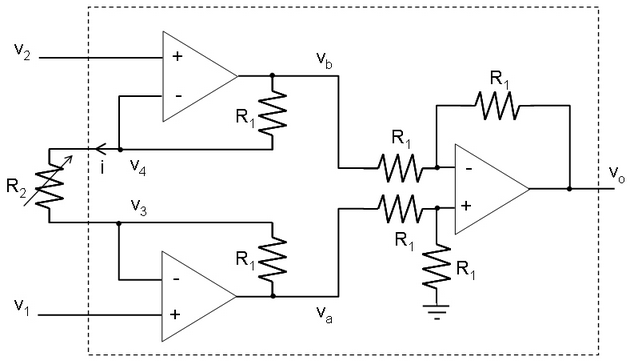

syms v_1 v_2 v_o v_b i v_3 v_4

constants = [
    R_1 == 30e3
    R_2 == 3.6e3
    v_1 == 4.97
    v_2 == 5.03
    v_3 == v_1
    v_4 == v_2
]

$$constants = \left(\begin{array}{c} R_{1}=30000\\ R_{2}=3600\\ v_{1}=4.9700\\ v_{2}=5.0300\\ v_{3}=v_{1}\\ v_{4}=v_{2} \end{array}\right)$$


% instrumentation_amp = v_o == -(v_2 - v_1) * (2 * R_1 / R_2 + 1)
kvl_3_4 = i == (v_4 - v_3) / R_2

$$kvl\_3\_4 = i=-\frac{v_{3}-v_{4}}{R_{2}}$$

kvl_b = v_b == v_4 + i * R_1

$$kvl\_b = v_{b}=v_{4}+R_{1}\,i$$


solve_for(v_b, [constants; kvl_b; kvl_3_4])

$$ans = 5.5300$$

**Question 6**

A square wave generator is connected as shown below, with R1 = R2 = 6.8kΩ, VoH=15V, voL=-15V, R3 = 120kΩ, and C=1μF. What is the frequency of oscillation of the output? (Enter answer in Hz)  

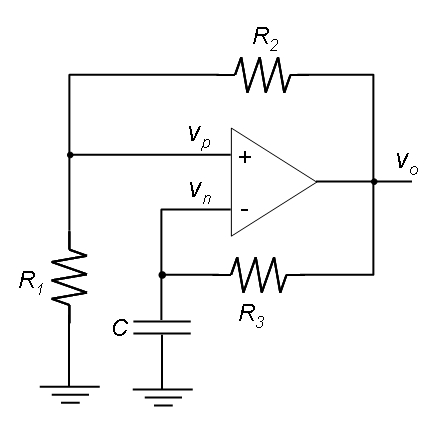

syms C v_oH v_oL v_pH v_pL T f

constants = [
    R_1 == 6.8e3
    R_2 == R_1
    R_3 == 120e3
    C == 1e-6
    v_oH == 15
    v_pL == -v_pH
    T == f^-1
]

$$constants = \left(\begin{array}{c} R_{1}=6800\\ R_{2}=R_{1}\\ R_{3}=120000\\ C=1.0000e-06\\ v_{\mathrm{oH}}=15\\ v_{\mathrm{pL}}=-v_{\mathrm{pH}}\\ T=\frac{1}{f} \end{array}\right)$$


cap_discharge = v_pH == v_oH + (v_pL - v_oH) * exp(-T / (2 * R_3 * C))

$$cap\_discharge = v_{\mathrm{pH}}=v_{\mathrm{oH}}-{\mathrm{e}}^{-\frac{0.5000\,T}{C\,R_{3}}}\,\left(v_{\mathrm{oH}}-v_{\mathrm{pL}}\right)$$

vdiv_p_o = v_pH == vdiv(v_oH, R_2, R_1)

$$vdiv\_p\_o = v_{\mathrm{pH}}=\frac{R_{1}\,v_{\mathrm{oH}}}{R_{1}+R_{2}}$$


solve_for(f, [constants; cap_discharge; vdiv_p_o])

$$ans = 3.7927$$

**Question 7 **     

A circuit in the inverting amplifier configuration is shown below. Derive the transfer function Vo/Vin. If R 1=1.5kΩ, R 2=10kΩ, R 3=R 1//R 2, and C 1=15μF, what is the 3dB frequency of the pole created by this circuit? (Enter answer in Hz, eg 10Hz is entered as 10) 

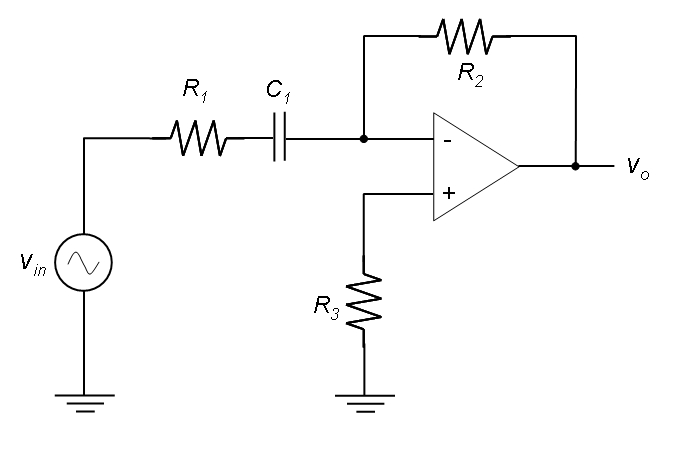

syms C_1 i v_in(t) v_o(t) s

constants = [
    R_1 == 1.5e3
    R_2 == 10e3
    R_3 == zpar([R_1 R_2])
    C_1 == 15e-6
    f == s / (2 * pi)
]

$$constants = \left(\begin{array}{c} R_{1}=1500\\ R_{2}=10000\\ R_{3}=\frac{R_{1}\,R_{2}}{R_{1}+R_{2}}\\ C_{1}=1.5000e-05\\ f=0.1592\,s \end{array}\right)$$


gain = s*C_1*R_2 / (1 + s*C_1*R_1)

$$gain = \frac{C_{1}\,R_{2}\,s}{C_{1}\,R_{1}\,s+1}$$

cutoff_freq = -3 == 20 * log10(gain)

$$cutoff\_freq = -3=8.6859\,\log\left(\frac{C_{1}\,R_{2}\,s}{C_{1}\,R_{1}\,s+1}\right)$$


solve_for(f, [constants; cutoff_freq])

$$ans = 0.8404$$


% differentiator = -v_o / R_2 == C_1 / R_1 * diff(v_in)
% laplace_domain = laplace(differentiator)
% 
% % solve_for(v_o / v_in, [constants; laplace_domain], s)
% % need to do some work on the engine to support solving for fractions
% % the result is -(1.0000e-04*v_o)/s == 1.0000e-08*v_in
% % rearranging: v_o / v_in == -1e-8 * s / 1e-4 == 1e-4 * s
% 
% gain = A_v == 1e-4 * s
% gain_dB = 3 == 20 * log10(abs(A_v))
% s_to_f = f == s / (2 * pi)
% 
% solve_for(f, [gain_dB; gain; s_to_f])
% % wants answer in hz, doesn't seem right...

**Question 8**

A prototype first order low pass stage is shown below, with R1 = 1Ω, C = 1F, R2 = 1.3Ω, and R3 = 4Ω,   If the circuit is to be scaled so that the cutoff frequency is 8kHz, and the new value of C = 3.3nF, what is the new value of R1? (Answer in kΩ , eg 0.1 kΩ is entered as 0.1)  

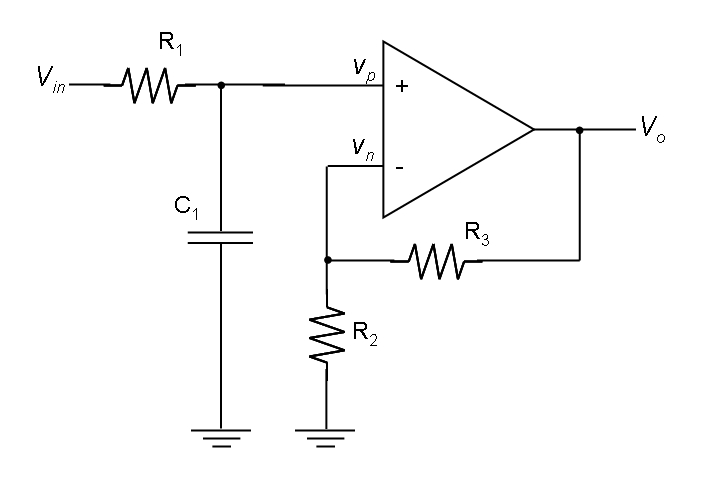

syms f_co_1 f_co_2 K_m K_f R_1_2 C_2 A_v s_co_1

constants = [
    R_1 == 1
    C == 1
    R_2 == 1.3
    R_3 == 4
    f_co_2 == 8e3
    f_co_1 == s_co_1 / (2 * pi)
    C_2 == 3.3e-9
]

$$constants = \left(\begin{array}{c} R_{1}=1\\ C=1\\ R_{2}=1.3000\\ R_{3}=4\\ f_{\mathrm{co},2}=8000\\ f_{\mathrm{co},1}=0.1592\,s_{\mathrm{co},1}\\ C_{2}=3.3000e-09 \end{array}\right)$$


orig_gain = 1 / (1 + s_co_1 * C * R_1) / vdiv(1, R_3, R_2)

$$orig\_gain = \frac{R_{2}+R_{3}}{R_{2}\,\left(C\,R_{1}\,s_{\mathrm{co},1}+1\right)}$$

orig_cutoff_freq = -3 == 20 * log10(orig_gain)

$$orig\_cutoff\_freq = -3=8.6859\,\log\left(\frac{R_{2}+R_{3}}{R_{2}\,\left(C\,R_{1}\,s_{\mathrm{co},1}+1\right)}\right)$$

scaler_f = K_f == f_co_2 / f_co_1

$$scaler\_f = K_{f}=\frac{f_{\mathrm{co},2}}{f_{\mathrm{co},1}}$$

scaler_m = C_2 == C / (K_f * K_m)

$$scaler\_m = C_{2}=\frac{C}{K_{f}\,K_{m}}$$

scaled_R_1 = R_1_2 == K_m * R_1

$$scaled\_R\_1 = R_{1,2}=K_{m}\,R_{1}$$


solve_for(R_1_2, [
    constants
    orig_cutoff_freq
    scaler_f
    scaler_m
    scaled_R_1
])

$$ans = 2.8689e+04$$

**Question 9**

A prototype LC Ladder circuit implementing a 4th order Butterworth lowpass filter is shown below. This circuit is normalised so that R1 and R2 are 1Ω, and the 3dB cutoff frequency is 1rad/s.We wish to scale the circuit so that the cutoff frequency is 300kHz, and the new values of both R1 and R2 are 50Ω. What is the new value of inductor L2, after frequency and magnitude scaling? (Enter answer in μH, eg, 150 μH is entered as 150)  Note: This question is about scaling component values.  Whether or not we have talked about this circuit topology in class should not  affect your ability to complete this question.

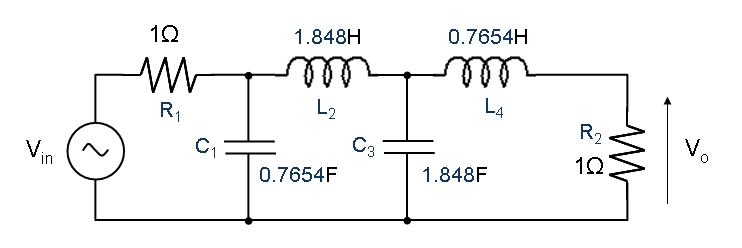

syms L_2_1 L_2_2 R_1_1 R_1_2 s_co_2

constants = [
    R_1_1 == 1
    s_co_1 == 1
    f_co_2 == 300e3
    f_co_2 == s_co_2 / (2 * pi)
    R_1_2 == 50
    L_2_1 == 1.848
]

$$constants = \left(\begin{array}{c} R_{1,1}=1\\ s_{\mathrm{co},1}=1\\ f_{\mathrm{co},2}=300000\\ f_{\mathrm{co},2}=0.1592\,s_{\mathrm{co},2}\\ R_{1,2}=50\\ L_{2,1}=1.8480 \end{array}\right)$$


freq_scale = K_f == s_co_2 / s_co_1

$$freq\_scale = K_{f}=\frac{s_{\mathrm{co},2}}{s_{\mathrm{co},1}}$$

mag_scale = R_1_2 == K_m * R_1_1

$$mag\_scale = R_{1,2}=K_{m}\,R_{1,1}$$

inductor_scale = L_2_2 == L_2_1 * K_m / K_f

$$inductor\_scale = L_{2,2}=\frac{K_{m}\,L_{2,1}}{K_{f}}$$


solve_for(L_2_2, [
    constants

    freq_scale
    mag_scale
    inductor_scale
])

$$ans = 4.9020e-05$$

**Question 10**

A low pass filter is to be designed with the following parameters:        passband edge frequency (w p) = 10kHz stopband edge frequency (w s) =  30kHz Maximum passband attenuation (A max)= 1.0 dB Minimum stopband attenuation (A min) = 40 dB    What order of Chebyshev filter is required to meet these specifications? (Enter integer)    

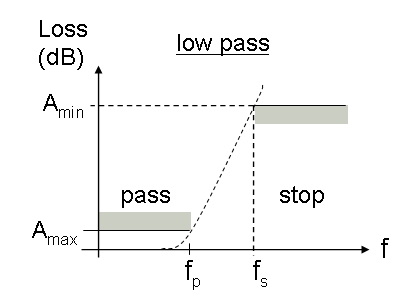

syms w_p w_s A_max A_min epsilon n

constants = [
    A_min == 40
    A_max == 1
    w_p == 10e3
    w_s == 30e3
]

$$constants = \left(\begin{array}{c} A_{\min}=40\\ A_{\max}=1\\ w_{p}=10000\\ w_{s}=30000 \end{array}\right)$$


eps_eq = epsilon == sqrt(10^(0.1 * A_max) - 1)

$$eps\_eq = \epsilon =\sqrt{10^{0.1000\,A_{\max}}-1}$$

chebyshev_order = n == ...
    acosh(sqrt((10^(0.1*A_min)-1)/epsilon^2)) / acosh(w_s / w_p)

$$chebyshev\_order = n=\frac{\mathrm{acosh}\left(\sqrt{\frac{10^{0.1000\,A_{\min}}-1}{\epsilon^{2}}}\right)}{\mathrm{acosh}\left(\frac{w_{s}}{w_{p}}\right)}$$


solve_for(ceil(n), [
    constants
    eps_eq
    chebyshev_order
])

$$ans = 3.3890$$

**Question 11**

The second order highpass Sallen-Key stage below is to be used to  implement one stage of a Chebyshev filter, whose transfer function is  given in Equation (1). We wish to calculate a protoype circuit that can  be scaled to the required cutoff frequency.    If prototype values for C 1 = C 2 = 1F, and K = 5, what is the prototype value for R 2? (Enter answer in Ω, eg 1.5Ω is entered as 1.5).

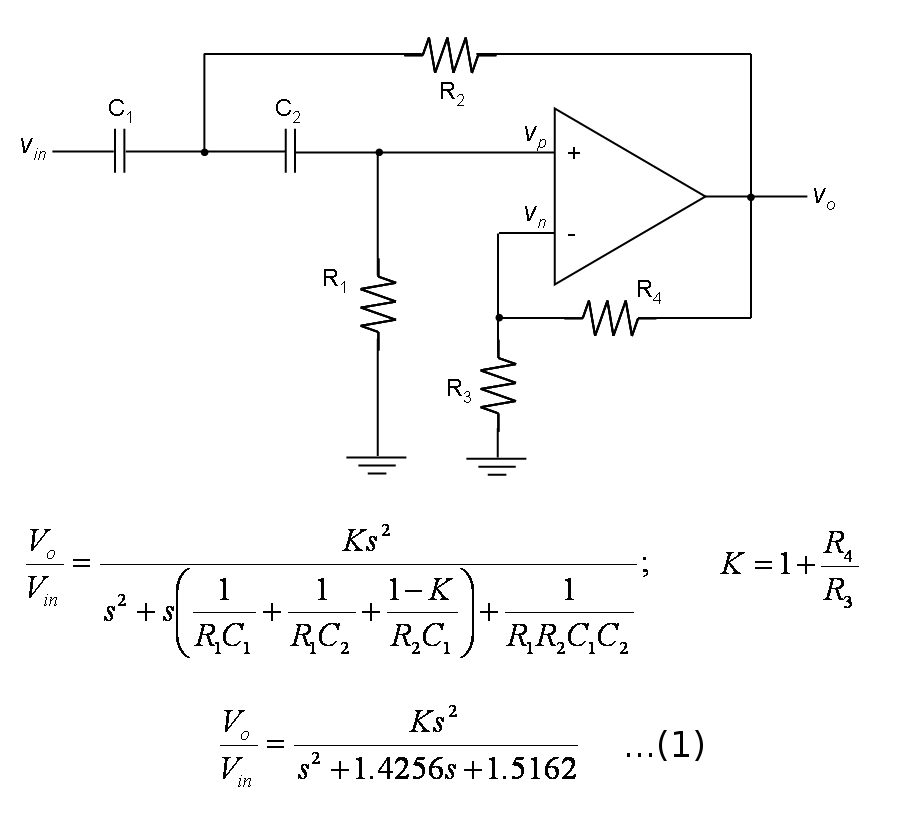

syms K

constants = [
    C_1 == C_2
    C_2 == 1
    K == 5
]

$$constants = \left(\begin{array}{c} C_{1}=C_{2}\\ C_{2}=1\\ K=5 \end{array}\right)$$


gain_eq = K * s^2 / (s^2 + 1.4256 * s + 1.5162) == ...
    K * s^2 / (s^2 + s*(1/(R_1*C_1) + 1/(R_1*C_2)+(1-K)/(R_2*C_1)) + 1/(R_1*R_2*C_1*C_2))

$$gain\_eq = \frac{K\,s^{2}}{s^{2}+1.4256\,s+1.5162}=\frac{K\,s^{2}}{s^{2}+s\,\left(\frac{1}{C_{1}\,R_{1}}+\frac{1}{C_{2}\,R_{1}}-\frac{K-1}{C_{1}\,R_{2}}\right)+\frac{1}{C_{1}\,C_{2}\,R_{1}\,R_{2}}}$$

% would be nice if we could chuck this in directly, but we need to manually
% split it up instead:
b = 1.4256 == 1/(R_1*C_1) + 1/(R_1*C_2)+(1-K)/(R_2*C_1)

$$b = 1.4256=\frac{1}{C_{1}\,R_{1}}+\frac{1}{C_{2}\,R_{1}}-\frac{K-1}{C_{1}\,R_{2}}$$

c = 1.5162 == 1 / (R_1 * R_2 * C_1 * C_2)

$$c = 1.5162=\frac{1}{C_{1}\,C_{2}\,R_{1}\,R_{2}}$$


solve_for([R_2 R_1], [constants; b; c])

$$ans = \left(\begin{array}{cc} -0.9373 & -0.7037\\ 1.4074 & -0.7037\\ -0.9373 & 0.4686\\ 1.4074 & 0.4686 \end{array}\right)$$